## **        1. Load and display the raw data**

% Raw sinyali .txt dosyasından yükleyeceğiz ve 4 kanalı görüntüleyeceğiz

clc
clearvars

[filename,pathname] = uigetfile('.txt');    % let the user choose the raw data

fullpath = strcat(pathname,filename);        % combine the path and filenames
Raw = readmatrix(fullpath);       % read the raw data as matrix named 'Raw'
Report = table;
Report.Vars_Name{1} = 'File path:';
Report.Vars{1} = fullpath;
clear filename fullpath


Report.Vars_Name{2} = 'Vaka ID:';

prompt = 'Vaka kodunu giriniz: ';
dlgtitle = 'Case ID';
dims = [1 30];
definput = {'ED_'};
Report.Vars{2} = inputdlg(prompt,dlgtitle,dims,definput);
clear definput dims dlgtitle prompt


prompt = 'Örneklem frekansını giriniz (Hz): ';
dlgtitle = 'Ö.F. (Hz)';
dims = [1 30];
definput = {'500'};
Fs = cell2mat(inputdlg(prompt,dlgtitle,dims,definput,"on"));   %Sampling Frequency of raw data
Fs = str2double(Fs);
Report.Vars_Name{3} = 'Örneklem Frekansı (Hz):';

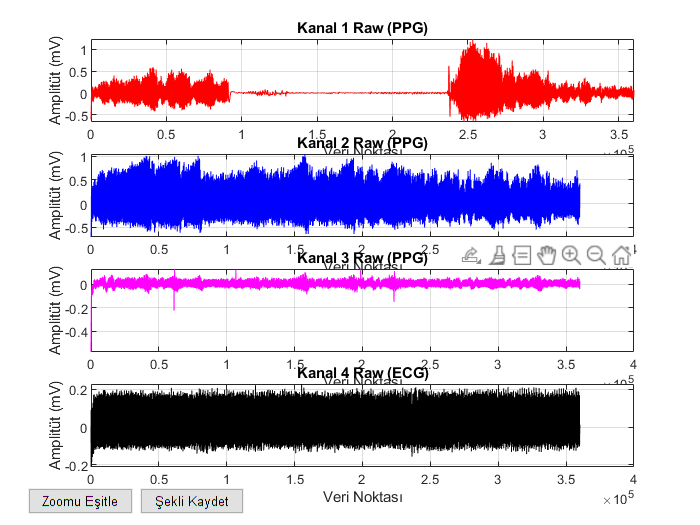

Report.Vars{3} = Fs;            % if you need Fs, use 'Report.Vars{3}' instead
clear definput dims dlgtitle prompt Fs



fig1 = figure;
subplot(4,1,1);
plot(Raw(:,1),'r')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
title 'Kanal 1 Raw (PPG)'
grid on;
xlim ([0 length(Raw(:,1))])
g1 = gca;

subplot(4,1,2);
plot(Raw(:,2),'Color','b')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
title 'Kanal 2 Raw (PPG)'
grid on;
g2 = gca;

subplot(4,1,3);
plot(Raw(:,3),'Color','m')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
title 'Kanal 3 Raw (PPG)'
grid on;
g3 = gca;

subplot(4,1,4);
plot(Raw(:,4),'Color','black')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
title 'Kanal 4 Raw (ECG)'
grid on;
g4 = gca;
fig_title = ['\1_' cell2mat(Report.Vars{2}) '_Raw Sinyal.png'];
uicontrol("Style","pushbutton","String",'Zoomu Eşitle',"units","normalized",...
    "Position", [0.04 0.02 0.15 0.05], ...
    "Callback",{@equalize_zoom_callback, g1,g2,g3,g4});
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.05], "Callback", {@save_fig_callback,fig1,fig_title,pathname});

 
 clear g1 g2 g3 g4 fig_title fig1 

## **2. Cut the raw data**

### **2.1 Select the indicator time points**

% In this section, we will specify the important time points
...to divide the signal into segments

global p_base_s p_base_e p_rep_s p_rep_e;

subplot(2,1,1)
plot(Raw(:,1),'r',"LineWidth",0.8)   % display the ch1 raw signal
p1=gca;
grid on
chr = ('Kanal 1 Raw Sinyal');
chr = [chr newline 'Lütfen fırça aracı ile belirteç noktalarını seçiniz'];
title(chr,"FontSize",12)

subplot(2,1,2)
plot(Raw(:,2),'b',"LineWidth",0.8)
p2=gca;
title 'Kanal 2 Raw Sinyal';
grid on

h=brush;
h.Color = 'green';
set(h,'Enable','on')
h=findobj(gca,'type','line');
uicontrol( "Style","pushbutton","String",'Select Baseline Start', ...
    "Units","normalized","Position", [0.04 0.01 0.15 0.05], "Callback", {@brush_base_s_callback,p_base_s});
uicontrol( "Style","pushbutton","String",'Select Baseline End', ...
    "Units","normalized","Position", [0.25 0.01 0.15 0.05], "Callback", {@brush_base_e_callback,h,p_base_e});
uicontrol( "Style","pushbutton","String",'Select Reperfusion Start', ...
    "Units","normalized","Position", [0.50 0.01 0.15 0.05], "Callback", {@brush_rep_s_callback,h,p_rep_s});
uicontrol( "Style","pushbutton","String",'Select Reperfusion End', ...
    "Units","normalized","Position", [0.75 0.01 0.15 0.05], "Callback", {@brush_rep_e_callback,h,p_rep_e});
while p1.Interruptible == 1   % p1 aktif, figür açık iken
   pause(1);                % 1 saniye bekle
   p2.XLim = p1.XLim;       % p2'nin X limitini, p1'in X limitine eşitle
end




### 2.2 Cut and display the raw data


clear h chr p1 p2  % bölüm 2.1'deki objeleri sil
clear Raw_cutted

Raw_cutted(:,1) = Raw(p_base_s:p_rep_e,1);
Raw_cutted(:,2) = Raw(p_base_s:p_rep_e,2);
Raw_cutted(:,3) = Raw(p_base_s:p_rep_e,3);
Raw_cutted(:,4) = Raw(p_base_s:p_rep_e,4);
% we cutted the whole signal's extra points
... before baseline and after reperfusion period
  
    

p_base_s_2  = 1;
p_base_e_2   = p_base_e-p_base_s;  % indicator time points for Raw_cutted
p_rep_s_2   = p_rep_s-p_base_s;  % different from time points for Raw
p_rep_e_2   = length(Raw_cutted(:,1));

ch1_1 = Raw_cutted(:,1); % no raw anymore

ch1_1(p_base_e_2+1:p_rep_s_2-1) = mean(ch1_1);   % we set the occlison period data
... to the mean value of ch1_1 signal. ideally mean(ch1_1) = 0
    ch1_1 = ch1_1 - mean(ch1_1);             % we subtract the mean(ch1_1) from every
    ch2_1 = Raw_cutted(:,2) - mean(Raw_cutted(:,2));        ... measurement value. this mean we applied a '0 Hz' or DC filter to our signal
    ch3_1 = Raw_cutted(:,3) - mean(Raw_cutted(:,3));        ... because we want to deal just with the AC component of the signal
    ch4_1 = Raw_cutted(:,4) - mean(Raw_cutted(:,4));



fig1=figure;
plot(Raw_cutted(:,1))
hold on
plot(ch1_1,'r')
legend 'Kanal 1 Raw Kesilmiş Sinyal' ' Kanal 1 DC (0 Hz) Filtrelenmiş Sinyal'
hold off
title 'Kanal 1 Ham Kesilmiş ve Filtrelenmiş Sinyal'
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
grid on
xlim ([0 length(Raw_cutted(:,1))])
fig_title = ['\2_' cell2mat(Report.Vars{2}) '_Kanal 1 Raw Kesilmiş ve DC Filtrelenmiş Sinyal.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear  fig1 fig_title



fig1 = figure;
hold on
subplot(4,1,1);
plot(ch1_1,'r')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
chr = 'Kesilmiş ve DC Filtrelenmiş Sinyaller';
chr = [chr newline 'Kanal 1 (PPG)'] ;
grid on;
xlim ([0 length(ch1_1(:,1))])
g1 = gca;
g1.Title.String = chr;

subplot(4,1,2);
plot(ch2_1,'Color','b')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
title 'Kanal 2 (PPG)'
grid on;
g2 = gca;

subplot(4,1,3);
plot(ch3_1,'Color','m')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
title 'Kanal 3 (PPG)'
grid on;
g3 = gca;

subplot(4,1,4);
plot(ch4_1,'Color','black')
xlabel 'Veri Noktası'
ylabel 'Amplitüt (mV)'
title 'Kanal 4 (ECG)'
grid on;
g4 = gca;
fig_title = ['\3_' cell2mat(Report.Vars{2}) '_Raw Kesilmiş ve DC Filtrelenmiş Sinyal.png'];
uicontrol( "Style","pushbutton","String",'Save Figure', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.05], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
while g1.Interruptible == 1   % p1 aktif, figür açık iken
   pause(1);                % 1 saniye bekle
   g2.XLim = g1.XLim;       % p2'nin X limitini, p1'in X limitine eşitle
   g3.XLim = g1.XLim;
   g4.XLim = g1.XLim;
end


clear fig1 fig_title g1 g2 g3 g4


## **   3. Baseline analysis**

### **        3.1. Finding the main frequency and minimum interpeak distance**

% In this section, we will analyse the baseline characteristic
... we will take the Fast Fourier Transfer of the ch1 baseline signal
    ... we are goint to calculate the main frequency and minimum interpeaks distance of the signal
    

ch1_bsl = ch1_1(1:(p_base_e_2-p_base_s_2)); % channel 1 baseline signal


% finding the minimum inter-peak distance

L = length(ch1_bsl);             % Length of signal
Y = fft(ch1_bsl);  % ppg dalgamızın fft'sini aldık
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Report.Vars{3}*(0:(L/2))/L;   % f bizim x eksenimiz, frekansı gösteriyor


n=1;                    % burada fft sinyalinin 0.5Hz ile 3Hz arasını kesiyoruz
for i = 1:length(P1)    % çünkü fizyolojik nabız sınırlarını 30-180 bpm olarak düşündük
    if f(i) > 0.5 && f(i) < 3
        pulse_fft(n,1) = f(i); %#ok<SAGROW>
        pulse_fft(n,2) = P1(i); %#ok<SAGROW>
        n=n+1;
    end
end
clear n i


fig1 = figure;
plot(pulse_fft(:,1),pulse_fft(:,2),'r', "LineWidth",1.5);     % fft grafiğimiz. frekansa karşışık o frekansın sinyaldeki hacmi
xlim([0.5 3.0])
y_lim_up = max(pulse_fft(:,2))*1.1;
ylim([0 y_lim_up])
xlabel 'Frekans (Hz)';
ylabel 'Yoğunluk (|P1(f)|)';
title 'Kanal 1 Baseline FFT Sonuç Grafiği';
grid on
fig_title = ['\4_' cell2mat(Report.Vars{2}) '_Kanal 1 Baseline FFT.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



[~,x_fft] = max(pulse_fft(:,2)); % y ekseninde maksimum noktanın x eksenindeki koordinatını bulduk
ch1_bsl_main_freq = pulse_fft(x_fft,1);  % bu maksimumun frekans değerini aldık
ch1_bsl_ipd = round((Report.Vars{3}/ch1_bsl_main_freq)*0.65);

Report.Vars_Name{4} = 'Baseline main frequency (Hz):';
Report.Vars{4} = round(ch1_bsl_main_freq,2);

Report.Vars_Name{5} = 'Baseline minimum IPD (points):';
Report.Vars{5} = ch1_bsl_ipd;

clear L Y P1 P2 f pulse_fft y_lim_up ...
    x_fft ch1_bsl_main_freq ch1_bsl_ipd 


###         3.2. Finding ch1 baseline peaks and displaying the amplitudes


clear ch1_bsl_p_peaks ch1_bsl_n_peaks
[ch1_bsl_p_peaks(:,2), ch1_bsl_p_peaks(:,1)] = findpeaks(ch1_bsl,...
    'MinPeakDistance',Report.Vars{5}); % this will find the positive peaks of ch1_bsl signal
% we take x and y coordinates of positive peaks

ch1_bsl_neg = ch1_bsl*-1;          % we reverse the signal to find negative peaks

[ch1_bsl_n_peaks(:,2), ch1_bsl_n_peaks(:,1)] = findpeaks(ch1_bsl_neg,...
    'MinPeakDistance',Report.Vars{5});  % find the nagative peaks and take the coordinates
ch1_bsl_n_peaks(:,2) = ch1_bsl_n_peaks(:,2)*-1;                                               % reverse the y coordinates because signal was also reversed
clear ch1_bsl_neg

chr = num2str(length(ch1_bsl_n_peaks));
chr = [chr ' negatif pik ve '];     % we define a massage dialog box
chr = [chr num2str(length(ch1_bsl_p_peaks))];
chr = [chr ' positif pik bulundu'];
dlgtitle = 'Baseline pik';


if length(ch1_bsl_n_peaks) == length(ch1_bsl_p_peaks)   % if we found equal number of peaks
    chr = [chr newline 'Herşey yolunda görünüyor'];
    msgbox(chr,dlgtitle,"help");
elseif length(ch1_bsl_n_peaks) ~= length(ch1_bsl_p_peaks) % and if we did not
    chr = [chr newline 'Devam etmek için eşit sayıda negatif ve pozitif pik olmalıdır'];
    chr = [chr newline 'Baseline sinyalini gözden geçirin'];
    msgbox(chr,dlgtitle,"error");
end
clear chr dlgtitle



fig1 = figure;
plot(ch1_bsl, 'r','LineWidth',1.5)                                  % plot the signal itself
hold("on");
plot(ch1_bsl_p_peaks(:,1),ch1_bsl_p_peaks(:,2),'b*','MarkerSize',10,"LineWidth",1.2);       % add positive peaks
hold("on");
plot(ch1_bsl_n_peaks(:,1),ch1_bsl_n_peaks(:,2),'g*','MarkerSize',10,"LineWidth",1.2);       % add negative peaks
hold off
title 'Kanal 1 Baseline Pozitif ve Negatif Pikler';
xlabel 'Veri Noktası';
ylabel 'Amplitüt (mV)';
grid on;
xlim ([0 length(ch1_bsl(:,1))])
fig_title = ['\5_' cell2mat(Report.Vars{2}) '_Kanal 1 Baseline Sinyali ve Pik Noktalar.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



clear ch1_bsl_amp
if length(ch1_bsl_n_peaks) == length(ch1_bsl_p_peaks)
    ch1_bsl_amp(:,1) = ch1_bsl_n_peaks(:,1); % amplitud serimizin x eksenini nefatif piklerin koordinatlarına eşitledik
    ch1_bsl_amp(:,2) = ch1_bsl_p_peaks(:,2) - ch1_bsl_n_peaks(:,2);
end      % pozitif piklerin Y değerlerinden negatif piklerin Y değerini
    % çıkararak tüm seri için amplitüt değerlerini hesapladık

    
fig1 = figure;
plot((1:1:length(ch1_bsl_amp)),ch1_bsl_amp(:,2),'*b','MarkerSize',8,"LineWidth",1.1); % baseline amplitüt scatter plot'u göster
title 'kanal 1 Baseline Amplitüt Saçılım Grafiği';
xlim ([0 length(ch1_bsl_amp)+1])            % her bir nokta bir nabız dalgasına ya da kardiyak siklusa denk gelmektedir
xlabel 'Nabız Dalga Numarası'
ylabel 'Amplitüt (mV)'
grid on
fig_title = ['\6_' cell2mat(Report.Vars{2}) '_Kanal 1 Baseline Amplitüt Saçılım Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



###       3.3. Kanal 1 Baseline Analiz


clear ch1_bsl_sd ch1_bsl_slc ch1_bsl_slc_amp
z = length(ch1_bsl_amp);
l=1;        % Baseline sinyalimizi tarayacak, FMD analizi için en uygun baseline parçasını seçecek bir tarama penceresi oluşturuyoruz
k=60;       % tarama penceremizin genişliği (nabız dalgası biriminde) - 1 dakikaya denk gelecek şekilde güncellenebilir (main_freq*60)
ch1_bsl_sd = zeros(z-k+1,1);
for i=k:z
    ch1_bsl_sd(l,1) = std(ch1_bsl_amp(i-k+1:i,2)) / mean(ch1_bsl_amp(i-k+1:i,2)); % pencerenin analiz ettiği tüm parçalar için bir SD (Standart Sapma) değeri hesapladık
    l=l+1;
end
clear z l i


[a, b] = min(ch1_bsl_sd); % a is the minimum value of bsl_sd. a'th window has the minimum SD value
...                     b is the coordinate of the a on X axis
    
p_ch1_bsl_slc_s = ch1_bsl_n_peaks(b,1)-round(Report.Vars{5}/20);     % starting point of selected baseline
p_ch1_bsl_slc_e = ch1_bsl_p_peaks(b+59,1)+round(Report.Vars{5}/20);   % ending point of selected baseline

ch1_bsl_slc(:,2) = ch1_bsl(p_ch1_bsl_slc_s:p_ch1_bsl_slc_e);     % our selected baseline signal which include 'k' pulse cycle
ch1_bsl_slc(:,1)=p_ch1_bsl_slc_s:1:p_ch1_bsl_slc_e;


ch1_bsl_slc_amp(:,1) = b:1:b+k-1;
ch1_bsl_slc_amp(:,2) = ch1_bsl_amp(b:b+k-1,2);              % amplitud series of selected baseline signal
clear k


fig1=figure;
subplot(3,1,1)
plot(ch1_bsl,"LineWidth",1.2)
hold on
plot(ch1_bsl_slc(:,1), ch1_bsl_slc(:,2),'r', "LineWidth",1.2)
grid on
xlim([0 length(ch1_bsl)])
legend 'Tüm baseline sinyali' 'Seçilmiş baseline parçası'
title 'Kanal 1 Baseline Sinyali'
xlabel 'Ölçüm Noktası'
ylabel 'Amlplitüt (mV)'
hold off

subplot(3,1,2)
plot((1:1:length(ch1_bsl_amp)),ch1_bsl_amp(:,2),'*',"LineWidth",1.2)
grid on
xlim ([0 length(ch1_bsl_amp)+2])
hold on
plot(ch1_bsl_slc_amp(:,1),ch1_bsl_slc_amp(:,2),'*r',"LineWidth",1.2)
legend 'Baseline amplitüt saçılma grafiği' 'Seçilmiş baseline amplitüt saçılma grafiği'
title 'Nabız Dalgası Amplitüt Saçılma Grafiği'
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amlplitüt (mV)'
hold off

subplot(3,1,3)
plot(ch1_bsl_sd,'x',"Color",'g',"LineWidth",2.0)
hold on
plot(b,a,'*r',"LineWidth",1.5)
grid on
xlim ([0 length(ch1_bsl_sd)+2])
legend 'Tarama penceresi SS/Amp sonuçları' 'Minimum SD/Amp noktası'
title 'Analiz Penceresi SS/Amp Sonuç Saçılma Grafiği'
xlabel 'Analiz Penceresi Numarası'
ylabel 'SS / Ortalama Amplitüt'
fig_title = ['\7_' cell2mat(Report.Vars{2}) '_Kanal 1 Baseline Analiz.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title

clear a b 


## 4. FMD Calculation

### 4.1. Reperfüzyon Periyodu 'ana frekans' ve 'ipd'



ch1_rep = ch1_1(p_rep_s_2:p_rep_e_2);

% FFT of ch1 reperfusion signal
clear t L Y P1 P2 f pulse_fft;
L = length(ch1_rep);             % Length of signal
Y = fft(ch1_rep);  % we applid FFT to the signal

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Report.Vars{3}*(0:(L/2))/L;   % f is our X axis on the FFT plot and represents frequency


n=1;                    % burada fft sinyalinin 0.5Hz ile 3Hz arasını kesiyoruz
for i = 1:length(P1)    % çünkü fizyolojik nabız sınırlarını 30-180 bpm olarak düşündük
    if f(i) > 0.5 && f(i) < 3
        pulse_fft(n,1) = f(i); %#ok<SAGROW>
        pulse_fft(n,2) = P1(i); %#ok<SAGROW>
        n=n+1;
    end
end
clear i n


fig1=figure;
plot(pulse_fft(:,1),pulse_fft(:,2),'r', "LineWidth",1.2)     % fft grafiğimiz. frekansa karşışık o frekansın sinyaldeki hacmi
xlim([0.5 3.0])
y_lim_up = max(pulse_fft(:,2))*1.1;
ylim([0 y_lim_up])
xlabel 'Frequency (Hz)';
ylabel 'Intensity (|P1(f)|)';
title 'Ch1 Reperfusion Period FFT Result';
grid on
fig_title = ['\8_' cell2mat(Report.Vars{2}) '_Kanal 1 Reperfüzyon FFT.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title


[~,x_fft] = max(pulse_fft(:,2)); % y ekseninde maksimum noktanın x eksenindeki koordinatını bulduk
ch1_rep_main_freq = pulse_fft(x_fft,1);  % bu maksimumun frekans değerini aldık
ch1_rep_ipd = round((Report.Vars{3}/ch1_rep_main_freq)*0.65);

Report.Vars_Name{6} = 'Kanal 1 Reperfüzyon Ana Frekansı (Hz):';
Report.Vars{6} = round(ch1_rep_main_freq,2);
Report.Vars_Name{7} = 'Kanal 1 Reperfüzyon minimum IPD (veri noktası):';
Report.Vars{7} = ch1_rep_ipd;

clear ch1_rep_main_freq ch1_rep_ipd
clear t T L Y P1 P2 f pulse_fft x_fft y_lim_up

### **4.2. Getting Reperfusion Period Amplitudes**


clear ch1_rep_p_peaks ch1_rep_n_peaks chr ch1_rep_amp

[ch1_rep_p_peaks(:,2), ch1_rep_p_peaks(:,1)] =...
    findpeaks(ch1_rep,'MinPeakDistance',Report.Vars{7}); % this will find the positive peaks of ch1_rep signal
% we take x and y coordinates of positive peaks  % we used the ch1 bsl ipd value.

ch1_rep_neg = ch1_rep*-1;          % we reverse the signal to find negative peaks

[ch1_rep_n_peaks(:,2), ch1_rep_n_peaks(:,1)] = ...
    findpeaks(ch1_rep_neg,'MinPeakDistance',Report.Vars{7});  % find the nagative peaks and take the coordinates
ch1_rep_n_peaks(:,2) = ch1_rep_n_peaks(:,2)*-1;
clear ch1_rep_neg

chr = num2str(length(ch1_rep_n_peaks));
chr = [chr ' negatif pik ve '];     % we define a massage dialog box
chr = [chr num2str(length(ch1_rep_p_peaks))];
chr = [chr ' positif pik bulundu'];

if length(ch1_rep_n_peaks) == length(ch1_rep_p_peaks)   % if we found equal number of peaks
    chr = [chr newline 'Herşey yolunda görünüyor'];
    msgbox(chr);
elseif length(ch1_rep_n_peaks) ~= length(ch1_rep_p_peaks) % and if we did not
    chr = [chr newline 'Kanal 1 reperfüzyon sinyalini gözden geçirin'];
    msgbox(chr);
end
clear chr


fig1=figure;
plot(ch1_rep, 'r','LineWidth',1.5)                                  % plot the signal itself
title 'Kanal 1 Reperfüzyon Sinyali ve Pik Noktaları'
hold("on");
plot(ch1_rep_p_peaks(:,1),ch1_rep_p_peaks(:,2),'b*','MarkerSize',12,"LineWidth",1.2);       % add positive peaks
hold("on");
plot(ch1_rep_n_peaks(:,1),ch1_rep_n_peaks(:,2),'g*','MarkerSize',12,"LineWidth",1.2);       % add negative peaks
hold off
grid on
xlim ([0 length(ch1_rep(:,1))])
fig_title = ['\9_' cell2mat(Report.Vars{2}) '_Kanal 1 Reperfüzyon Sinyali ve Pik Noktalar.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



if length(ch1_rep_n_peaks) == length(ch1_rep_p_peaks)
    ch1_rep_amp(:,1) = ch1_rep_n_peaks(:,1);
    ch1_rep_amp(:,2) = ch1_rep_p_peaks(:,2) - ch1_rep_n_peaks(:,2);
end % we calculate the amplitudes by subtracting negative peaks value from positive ones


fig1=figure;
plot(ch1_rep_amp(:,2),'*b','MarkerSize',8,"LineWidth",1.1); % displaying the baseline amplitudes as scatter plot
xlim ([0 length(ch1_rep_amp)+1]);                         % every point represent a pulse wave
title 'Kanal 1 Reperfüzyon Amplitüt Saçılım Grafiği'
grid on
xlabel 'Nabız Dalga Numarası'
ylabel 'Amplitüt (mV)'
fig_title = ['\10_' cell2mat(Report.Vars{2}) '_Kanal 1 Reperfüzyon Amplitüt Saçılım Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title


### **4.3 FMD Dilatasyon İndeksi'ni Hesapla**


clear a b ch1_fmd_result ch1_fmd_result_normalized fmd_raw

[a,~]=size(ch1_bsl_slc_amp); % seçtiğimiz baseline bölümündeki nabız dalgası sayısı
[b,~]=size(ch1_rep_amp);    % kanal 1 reperfüzyon bölümündeki nabız dalgası sayısı


fmd_raw(:,1) = -2*a+1:1:b;
fmd_raw(1:a,2)=ch1_bsl_slc_amp(:,2);
fmd_raw(a+1:2*a,2)=nan;
fmd_raw((2*a+1):(2*a+b),2)=ch1_rep_amp(:,2);


fig1=figure;
plot(fmd_raw(1:a,1),fmd_raw(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_raw(2*a+1:end,1),fmd_raw(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1)
xlim ([min(fmd_raw(:,1)) max(fmd_raw(:,1))])
title 'Kanal 1 Raw Amplitüt Saçılım Grafiği'
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amplitüt (mV)'
grid on
fig_title = ['\11_' cell2mat(Report.Vars{2}) '_FMD Raw.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title


clear fmd_n
fmd_n(:,1) = fmd_raw(:,1);
fmd_n(:,2)=((fmd_raw(:,2)-mean(ch1_bsl_slc_amp(:,2)))*100)/mean(ch1_bsl_slc_amp(:,2));
    % amplitüt sonuc dalgamızı, baseline amplitüt ortalaması 0 olarak
    % şekilde normalize ettik. Yani her bir dalganın amplitütünün, baseline amplitüt
    % ortalamızdan ne kadar farklı olduğunu hesapladık
    
[dilatation_index_y,dilatation_index_x] = max(fmd_n((2*a+1):(2*a+b),2));
chr = ('Maksimum Dilatasyon indeksi: %');
chr = [chr num2str(round(dilatation_index_y))];
  

y_down = min(fmd_n(:,2))*1.12;
y_up   = max(fmd_n(:,2))*1.20;
fig1=figure;
plot(fmd_n(1:a,1),fmd_n(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_n(2*a+1:end,1),fmd_n(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1);
xlim([min(fmd_n(:,1)) max(fmd_n(:,1))])
ylim([y_down y_up])
xlabel('Nabız Dalgası Numarası')
ylabel('Dilatasyon İndeksi (%)')
title('Normalize FMD Sonuç Grafiği')
hold on
grid on
plot(fmd_n(dilatation_index_x+2*a,1),fmd_n(dilatation_index_x+2*a,2),...
    '*','MarkerSize',8,"LineWidth",1.1,"Color",[0.1 0.99 0.9])
annotation("textbox","String",chr,"Units","normalized","Position",[0.6 0.9 0.0 0.0],"FitBoxToText","on");
fig_title = ['\12_' cell2mat(Report.Vars{2}) '_FMD N.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title chr y_down y_up


Report.Vars_Name{8} = 'FMD N Dilatasyon İndeksi (%):';
Report.Vars{8} = round(dilatation_index_y);
Report.Vars_Name{9} = 'FMD N T:';
Report.Vars{9} = round(dilatation_index_x);

clear dilatation_index_x dilatation_index_y


## 5. Kanal 2 Analizi

### 5.1 Kanal 2 Amplitütlerini Hesapla


clear ch2_bsl ch2_bsl_slc_1 ch2_bsl_p_peaks ch2_bsl_n_peaks
ch2_bsl = ch2_1(1:(p_base_e_2-p_base_s_2+40)); % Kanal 2 baseline raw
ch2_bsl_slc_1(:,1)=p_ch1_bsl_slc_s:1:p_ch1_bsl_slc_e;
ch2_bsl_slc_1(:,2) = ch2_bsl(p_ch1_bsl_slc_s:p_ch1_bsl_slc_e);     % kanal 1 baseline analizine göre seçilmiş kanal 2 baseline bölümü


%% Kanal 2 Baseline Amplitütleri
[ch2_bsl_p_peaks(:,2), ch2_bsl_p_peaks(:,1)] =...
    findpeaks(ch2_bsl,'MinPeakDistance',Report.Vars{5}); % this will find the positive peaks of ch1_bsl signal

ch2_bsl_neg = ch2_bsl*-1;          % we reverse the signal to find negative peaks

[ch2_bsl_n_peaks(:,2), ch2_bsl_n_peaks(:,1)] =...
    findpeaks(ch2_bsl_neg,'MinPeakDistance',Report.Vars{5});  % find the nagative peaks and take the coordinates
ch2_bsl_n_peaks(:,2) = ch2_bsl_n_peaks(:,2)*-1;                                               % reverse the y coordinates because signal was also reversed
clear ch2_bsl_neg

chr = num2str(length(ch2_bsl_n_peaks));
chr = [chr ' negatif pik ve '];     % we define a massage dialog box
chr = [chr num2str(length(ch2_bsl_p_peaks))];
chr = [chr ' positif pik bulundu'];
dlgtitle = 'Baseline pik';


if length(ch2_bsl_n_peaks) == length(ch2_bsl_p_peaks)   % if we found equal number of peaks
    chr = [chr newline 'Herşey yolunda görünüyor']
    msgbox(chr,dlgtitle,"help");
elseif length(ch2_bsl_n_peaks) ~= length(ch2_bsl_p_peaks) % and if we did not
    chr = [chr newline 'Devam etmek için eşit sayıda negatif ve pozitif pik olmalıdır'];
    chr = [chr newline 'Baseline sinyalini gözden geçirin'];
    msgbox(chr,dlgtitle,"error");
end
clear chr dlgtitle


fig1=figure;
plot(ch2_bsl, 'r','LineWidth',1.5)                                  % plot the signal itself
hold("on");
plot(ch2_bsl_p_peaks(:,1),ch2_bsl_p_peaks(:,2),'b*','MarkerSize',10,"LineWidth",1.2);       % add positive peaks
hold("on");
plot(ch2_bsl_n_peaks(:,1),ch2_bsl_n_peaks(:,2),'g*','MarkerSize',10,"LineWidth",1.2);       % add negative peaks
hold off
grid on
title 'Kanal 2 Baseline Sinyal ve Pik Noktalar'
xlabel 'Ölçüm Noktası'
ylabel 'Amplitüt (mV)'
xlim([0 length(ch2_bsl)])
fig_title = ['\13_' cell2mat(Report.Vars{2}) '_Kanal 2 Baseline Sinyali ve Pik Noktalar.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



if length(ch2_bsl_n_peaks) == length(ch2_bsl_p_peaks)
    ch2_bsl_amp(:,1) = ch2_bsl_n_peaks(:,1); % amplitud serimizin x eksenini nefatif piklerin koordinatlarına eşitledik
    ch2_bsl_amp(:,2) = ch2_bsl_p_peaks(:,2) - ch2_bsl_n_peaks(:,2);
end      % pozitif piklerin Y değerlerinden negatif piklerin Y değerini
    % çıkararak tüm seri için amplitüt değerlerini hesapladık

    
fig1=figure;    
plot((1:1:length(ch2_bsl_amp)),ch2_bsl_amp(:,2),'*b','MarkerSize',8,"LineWidth",1.1); % baseline amplitüt scatter plot'u göster
title 'Kanal 2 Baseline Amplitüt Saçılım Grafiği'
xlim ([0 length(ch2_bsl_amp)+1])            % her bir nokta bir nabız dalgasına ya da kardiyak siklusa denk gelmektedir
grid on
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amplitüt (mV)'
fig_title = ['\14_' cell2mat(Report.Vars{2}) '_Kanal 2 Baseline Amplitüt Saçılım Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



ch2_bsl_slc_1_amp(:,1) = ch1_bsl_slc_amp(:,1);
ch2_bsl_slc_1_amp(:,2) = ch2_bsl_amp(ch1_bsl_slc_amp(1,1):ch1_bsl_slc_amp(end,1),2);

% Kanal 2 Baseline Analiz


z = length(ch2_bsl_amp);
l=1;        % Baseline sinyalimizi tarayacak, FMD analizi için en uygun baseline parçasını seçecek bir tarama penceresi oluşturuyoruz
k=60;       % tarama penceremizin genişliği (nabız dalgası biriminde) - 1 dakikaya denk gelecek şekilde güncellenebilir (main_freq*60)
ch2_bsl_sd = zeros(z-k+1,1);
for i=k:z
    ch2_bsl_sd(l,1) = std(ch2_bsl_amp(i-k+1:i,2)) / mean(ch2_bsl_amp(i-k+1:i,2)); % pencerenin analiz ettiği tüm parçalar için bir SD (Standart Sapma) değeri hesapladık
    l=l+1;
end
clear z l i


[a, b] = min(ch2_bsl_sd); % a is the minimum value of bsl_sd. a'th window has the minimum SD value
...                     b is the coordinate of the a on X axis
    
p_ch2_bsl_slc_2_s = ch2_bsl_n_peaks(b,1)-round(Report.Vars{5}/20);     % starting point of selected baseline
p_ch2_bsl_slc_2_e = ch2_bsl_p_peaks(b+59,1)+round(Report.Vars{5}/20);   % ending point of selected baseline

ch2_bsl_slc_2(:,2) = ch2_bsl(p_ch2_bsl_slc_2_s:p_ch2_bsl_slc_2_e);     % our selected baseline signal which include 'k' pulse cycle
ch2_bsl_slc_2(:,1)=p_ch2_bsl_slc_2_s:1:p_ch2_bsl_slc_2_e;


ch2_bsl_slc_2_amp(:,1) = b:1:b+k-1;
ch2_bsl_slc_2_amp(:,2) = ch2_bsl_amp(b:b+k-1,2);              % amplitud series of selected baseline signal
clear k


fig1=figure;
subplot(3,1,1)
plot(ch2_bsl,"LineWidth",1.2)
hold on
plot(ch2_bsl_slc_2(:,1), ch2_bsl_slc_2(:,2),'r', "LineWidth",1.2)
grid on
xlim([0 length(ch2_bsl)])
legend 'Tüm baseline sinyali' 'Seçilmiş baseline parçası'
title 'Kanal 2 Baseline Sinyali'
xlabel 'Ölçüm Noktası'
ylabel 'Amlplitüt (mV)'
hold off

subplot(3,1,2)
plot((1:1:length(ch2_bsl_amp)),ch2_bsl_amp(:,2),'*',"LineWidth",1.2)
grid on
xlim ([0 length(ch2_bsl_amp)+2])
hold on
plot(ch2_bsl_slc_2_amp(:,1),ch2_bsl_slc_2_amp(:,2),'*r',"LineWidth",1.2)
legend 'Baseline amplitüt saçılma grafiği' 'Seçilmiş baseline amplitüt saçılma grafiği'
title 'Nabız Dalgası Amplitüt Saçılma Grafiği'
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amlplitüt (mV)'
hold off

subplot(3,1,3)
plot(ch2_bsl_sd,'x',"Color",'g',"LineWidth",2.0)
hold on
plot(b,a,'*r',"LineWidth",1.5)
grid on
xlim ([0 length(ch2_bsl_sd)+2])
legend 'Tarama penceresi SS/Amp sonuçları' 'Minimum SD/Amp noktası'
title 'Analiz Penceresi SS/Amp Sonuç Saçılma Grafiği'
xlabel 'Analiz Penceresi Numarası'
ylabel 'SS / Ortalama Amplitüt'
fig_title = ['\15_' cell2mat(Report.Vars{2}) '_Kanal 2 Baseline Analiz.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title

clear a b 



### 5.2 Kanal 2 reperfüzyon amplitütleri


clear ch2_rep ch2_rep_p_peaks ch2_rep_n_peaks ch2_rep_amp

ch2_rep = ch2_1(p_rep_s_2:p_rep_e_2);

[ch2_rep_p_peaks(:,2), ch2_rep_p_peaks(:,1)] = ...
    findpeaks(ch2_rep,'MinPeakDistance',Report.Vars{7}); % this will find the positive peaks of ch1_rep signal
% we take x and y coordinates of positive peaks  % we used the ch1 bsl ipd value.

ch2_rep_neg = ch2_rep*-1;          % we reverse the signal to find negative peaks

[ch2_rep_n_peaks(:,2), ch2_rep_n_peaks(:,1)] = ...
    findpeaks(ch2_rep_neg,'MinPeakDistance',Report.Vars{7});  % find the nagative peaks and take the coordinates
ch2_rep_n_peaks(:,2) = ch2_rep_n_peaks(:,2)*-1;
clear ch2_rep_neg

chr = num2str(length(ch2_rep_n_peaks));
chr = [chr ' negatif pik ve '];     % we define a massage dialog box
chr = [chr num2str(length(ch2_rep_p_peaks))];
chr = [chr ' positif pik bulundu'];

if length(ch2_rep_n_peaks) == length(ch2_rep_p_peaks)   % if we found equal number of peaks
    chr = [chr newline 'Herşey yolunda görünüyor'];
    msgbox(chr);
elseif length(ch2_rep_n_peaks) ~= length(ch2_rep_p_peaks) % and if we did not
    chr = [chr newline 'Kanal 2 reperfüzyon sinyalini gözden geçirin'];
    msgbox(chr);
end
clear chr


fig1=figure;
plot(ch2_rep, 'r','LineWidth',1.5)                                  % plot the signal itself
hold("on");
plot(ch2_rep_p_peaks(:,1),ch2_rep_p_peaks(:,2),'b*','MarkerSize',12,"LineWidth",1.2);       % add positive peaks
hold("on");
plot(ch2_rep_n_peaks(:,1),ch2_rep_n_peaks(:,2),'g*','MarkerSize',12,"LineWidth",1.2);       % add negative peaks
hold off
xlim([0 length(ch2_rep)])
title 'Kanal 2 Reperfüzyon Sinyali ve Pik Noktalar'
xlabel 'Ölçüm Noktası'
ylabel 'Amplitüt (mV)'
grid on
fig_title = ['\16_' cell2mat(Report.Vars{2}) '_Kanal 2 Reperfüzyon Sinyali ve Pik Noktalar.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title


if length(ch2_rep_n_peaks) == length(ch2_rep_p_peaks)
    ch2_rep_amp(:,1) = ch2_rep_n_peaks(:,1);
    ch2_rep_amp(:,2) = ch2_rep_p_peaks(:,2) - ch2_rep_n_peaks(:,2);
end % we calculate the amplitudes by subtracting negative peaks value from positive ones


fig1=figure;
plot(ch2_rep_amp(:,2),'*b','MarkerSize',8,"LineWidth",1.1); % displaying the baseline amplitudes as scatter plot
xlim ([0 length(ch2_rep_amp)+1]);
title 'Kanal 2 Reperfüzyon Amplitüt Saçılım Grafiği'
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amplitüt (mV)'
grid on
fig_title = ['\17_' cell2mat(Report.Vars{2}) '_Kanal 2 Reperfüzyon Amplitüt Saçılım Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



### 5.2 FMD D1'i Hesapla



m = mean(ch2_bsl_slc_1_amp(:,2));

ch2_cor_matrix_1 = 1 - ((ch2_rep_amp(:,2)-m)./ch2_rep_amp(:,2)) ;



y_down(1) = min(ch2_rep_amp(:,2))*0.9;
y_down(2) = min(ch2_cor_matrix_1)*0.9;
y_up(1)   = max(ch2_rep_amp(:,2))*1.13;
y_up(2)   = max(ch2_cor_matrix_1)*1.13;
fig1=figure;
plot(ch2_rep_amp(:,2),'*',"LineWidth",0.9)
hold on
plot(ch2_cor_matrix_1,'*',"LineWidth",0.9)
ylim([min(y_down) max(y_up)])
title 'FMD D1 Düzeltme Matriksi'
xlabel 'Nabız Dalga Numarası'
ylabel 'Amplitüt (mV)'
hold on
yl = yline(m,'-.m','Kanal 2 seçilmiş baseline 1 ortalaması');
yl.FontSize = 12;
yl.LineWidth = 1.0;
hold off
legend 'Kanal 2 reperfüzyon amplitütleri' 'Kanal 2 düzeltme katsayıları 1'
grid on
fig_title = ['\18_' cell2mat(Report.Vars{2}) '_FMD D1 Düzeltme Matriksi.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title


ch1_rep_cor_amp_1 = ch1_rep_amp(:,2).*(ch2_cor_matrix_1); % kanal 1 düzeltilmiş reperfüzyon amplitütleri


fig1=figure;
plot(ch1_rep_amp(:,2),'*',"LineWidth",0.9)
title 'Kanal 1 Raw ve D1 Düzeltilmiş Amplitüt Saçılma Grafiği'
hold on
plot(ch1_rep_cor_amp_1,'*',"LineWidth",0.9)
legend 'Kanal 1 raw reperfüzyon amplitütleri' 'Kanal 1 D1 reperfüzyon amplitütleri'
grid on
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amplitüt (mV)'
fig_title = ['\19_' cell2mat(Report.Vars{2}) '_Kanal 1 Raw ve D1 Düzeltilmiş Amplitüt Saçılma Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



fmd_d1 = fmd_raw;
fmd_d1(end-length(ch1_rep_cor_amp_1)+1:end,2) = ch1_rep_cor_amp_1; % fmd_d1'in reperfüzyon kısmına düzeltilmiş reperfüzyon değerlerini atadık

fmd_d1(:,2)=((fmd_d1(:,2)-mean(ch1_bsl_slc_amp(:,2)))*100)/mean(ch1_bsl_slc_amp(:,2));
    % amplitüt sonuc dalgamızı, baseline amplitüt ortalaması 0 olarak
    % şekilde normalize ettik. Yani her bir dalganın amplitütünün, baseline amplitüt
    % ortalamızdan ne kadar farklı olduğunu hesapladık
a = length(ch1_bsl_slc_amp);
[dilatation_index_y,dilatation_index_x] = max(fmd_d1((2*a+1):(end),2));
chr = ('Maksimum Dilatasyon indeksi: %');
chr = [chr num2str(round(dilatation_index_y))];
  

y_down = min(fmd_d1(:,2))*1.15;
y_up   = max(fmd_d1(:,2))*1.2;
a = length(ch1_bsl_slc_amp);
fig1=figure;
plot(fmd_d1(1:a,1),fmd_d1(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_d1(2*a+1:end,1),fmd_d1(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1);
xlim ([min(fmd_d1(:,1)) max(fmd_d1(:,1))])
ylim ([y_down y_up])
xlabel('Nabız Dalgası Numarası')
ylabel('Dilatasyon İndeksi (%)')
title('FMD D1 Sonuç Grafiği')
hold on
grid on
plot(fmd_d1(dilatation_index_x+2*a,1),fmd_d1(dilatation_index_x+2*a,2),...
    '*','MarkerSize',8,"LineWidth",1.1,"Color",[0.1 0.99 0.9])
annotation("textbox","String",chr,"Units","normalized","Position",[0.6 0.9 0.0 0.0],"FitBoxToText","on");
fig_title = ['\20_' cell2mat(Report.Vars{2}) '_FMD D1.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title


Report.Vars_Name{10} = 'FMD D1 Dilatasyon İndeksi (%):';
Report.Vars{10} = round(dilatation_index_y);
Report.Vars_Name{11} = 'FMD D1 T:';
Report.Vars{11} = round(dilatation_index_x);

clear dilatation_index_x dilatation_index_y


### 5.3 FMD D2'yi Hesapla


clear m
m = mean(ch2_bsl_slc_2_amp(:,2));

ch2_cor_matrix_2 = 1 - ((ch2_rep_amp(:,2)-m)./ch2_rep_amp(:,2)) ;


fig1=figure;
plot(ch2_rep_amp(:,2),'*',"LineWidth",0.9)
hold on
plot(ch2_cor_matrix_2,'*',"LineWidth",0.9)
title 'FMD D2 için Kanal 2 Reperfüzyon ve Düzeltme Katsayıları Sinyali'
xlabel 'Nabız Dalga Numarası'
ylabel 'Amplitüt (mV)'
hold on
yl = yline(m,'-.m','Kanal 2 seçilmiş baseline 2 ortalaması');
yl.FontSize = 12;
yl.LineWidth = 1.0;
hold off
legend 'Kanal 2 reperfüzyon amplitütleri' 'Kanal 2 düzeltme katsayıları 2'
grid on
fig_title = ['\21_' cell2mat(Report.Vars{2}) '_FMD D2 Düzeltme Matriksi.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title


ch1_rep_cor_amp_2 = ch1_rep_amp(:,2).*(ch2_cor_matrix_2); % kanal 1 düzeltilmiş reperfüzyon amplitütleri


fig1=figure;
plot(ch1_rep_amp(:,2),'*',"LineWidth",0.9)
title 'Kanal 1 Raw ve D2 Düzeltilmiş Amplitüt Saçılma Grafiği'
hold on
plot(ch1_rep_cor_amp_2,'*',"LineWidth",0.9)
legend 'Kanal 1 raw reperfüzyon amplitütleri' 'Kanal 1 D2 reperfüzyon amplitütleri'
xlim([0 length(ch1_rep_amp)])
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amplitüt (mV)'
grid on
fig_title = ['\22_' cell2mat(Report.Vars{2}) '_Kanal 1 Raw ve D2 Düzeltilmiş Amplitüt Saçılma Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title




fmd_d2 = fmd_raw;
fmd_d2(end-length(ch1_rep_cor_amp_2)+1:end,2) = ch1_rep_cor_amp_2; % fmd_d2'in reperfüzyon kısmına düzeltilmiş reperfüzyon değerlerini atadık

fmd_d2(:,2)=((fmd_d2(:,2)-mean(ch1_bsl_slc_amp(:,2)))*100)/mean(ch1_bsl_slc_amp(:,2));
    % amplitüt sonuc dalgamızı, baseline amplitüt ortalaması 0 olarak
    % şekilde normalize ettik. Yani her bir dalganın amplitütünün, baseline amplitüt
    % ortalamızdan ne kadar farklı olduğunu hesapladık
    
[dilatation_index_y,dilatation_index_x] = max(fmd_d2((2*a+1):(end),2));
chr = ('Maksimum Dilatasyon indeksi: %');
chr = [chr num2str(round(dilatation_index_y))];
a = length(ch1_bsl_slc_amp);


y_down = min(fmd_d2(:,2))*1.15;
y_up   = max(fmd_d2(:,2))*1.15;
fig1=figure;
plot(fmd_d2(1:a,1),fmd_d2(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_d2(2*a+1:end,1),fmd_d2(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1);
xlim ([min(fmd_d2(:,1)) max(fmd_d2(:,1))])
ylim ([y_down y_up])
xlabel('Nabız Dalgası Numarası')
ylabel('Dilatasyon İndeksi (%)')
title('FMD D2 Sonuç Grafiği')
hold on
grid on
plot(fmd_d2(dilatation_index_x+2*a,1),fmd_d2(dilatation_index_x+2*a,2),...
    '*','MarkerSize',8,"LineWidth",1.1,"Color",[0.1 0.99 0.9])
annotation("textbox","String",chr,"Units","normalized","Position",[0.6 0.9 0.0 0.0],"FitBoxToText","on");
clear chr
fig_title = ['\23_' cell2mat(Report.Vars{2}) '_FMD D2.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title y_down y_up



Report.Vars_Name{12} = 'FMD D2 Dilatasyon İndeksi (%):';
Report.Vars{12} = round(dilatation_index_y);
Report.Vars_Name{13} = 'FMD D2 T:';
Report.Vars{13} = round(dilatation_index_x);

clear dilatation_index_x dilatation_index_y


### 5.4 FMD D3'ü Hesapla


clear m
m = mean(ch2_bsl_amp(:,2));

ch2_cor_matrix_3 = 1 - ((ch2_rep_amp(:,2)-m)./ch2_rep_amp(:,2));


fig1=figure;
plot(ch2_rep_amp(:,2),'*',"LineWidth",0.9)
hold on
plot(ch2_cor_matrix_3,'*',"LineWidth",0.9)
title 'FMD D3 için Kanal 2 Reperfüzyon ve Düzeltme Katsayıları Sinyali'
xlabel 'Nabız Dalga Numarası'
ylabel 'Amplitüt (mV)'
hold on
yl = yline(m,'-.m','Kanal 2 baseline ortalaması');
yl.FontSize = 12;
yl.LineWidth = 1.0;
hold off
grid on
legend 'Kanal 2 reperfüzyon amplitütleri' 'Kanal 2 düzeltme katsayıları 3'
fig_title = ['\24_' cell2mat(Report.Vars{2}) '_FMD D3 Düzeltme Matriksi.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



ch1_rep_cor_amp_3 = ch1_rep_amp(:,2).*(ch2_cor_matrix_3); % kanal 1 düzeltilmiş reperfüzyon amplitütleri


fig1=figure;
plot(ch1_rep_amp(:,2),'*',"LineWidth",0.9)
title 'Kanal 1 Raw ve D3 Düzeltilmiş Amplitüt Saçılma Grafiği'
hold on
plot(ch1_rep_cor_amp_3,'*',"LineWidth",0.9)
legend 'Kanal 1 raw reperfüzyon amplitütleri' 'Kanal 1 D3 reperfüzyon amplitütleri'
xlim([0 length(ch1_rep_amp)])
xlabel 'Nabız Dalgası Numarası'
ylabel 'Amplitüt (mV)'
grid on
fig_title = ['\25_' cell2mat(Report.Vars{2}) '_Kanal 1 Raw ve D3 Düzeltilmiş Amplitüt Saçılma Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title



fmd_d3 = fmd_raw;
fmd_d3(end-length(ch1_rep_cor_amp_3)+1:end,2) = ch1_rep_cor_amp_3; % fmd_d2'in reperfüzyon kısmına düzeltilmiş reperfüzyon değerlerini atadık

fmd_d3(:,2)=((fmd_d3(:,2)-mean(ch1_bsl_slc_amp(:,2)))*100)/mean(ch1_bsl_slc_amp(:,2));
    % amplitüt sonuc dalgamızı, baseline amplitüt ortalaması 0 olarak
    % şekilde normalize ettik. Yani her bir dalganın amplitütünün, baseline amplitüt
    % ortalamızdan ne kadar farklı olduğunu hesapladık
    
[dilatation_index_y,dilatation_index_x] = max(fmd_d3((2*a+1):(end),2));
chr = ('Maksimum Dilatasyon indeksi: %');
chr = [chr num2str(round(dilatation_index_y))];


y_down = min(fmd_d3(:,2))*1.15;
y_up   = max(fmd_d3(:,2))*1.15;
fig1=figure;
a = length(ch1_bsl_slc_amp);
plot(fmd_d3(1:a,1),fmd_d3(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_d3(2*a+1:end,1),fmd_d3(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1);
xlim ([min(fmd_d3(:,1)) max(fmd_d3(:,1))])  
ylim ([y_down y_up])
xlabel('Nabız Dalgası Numarası')
ylabel('Dilatasyon İndeksi (%)')
title('FMD D3 Sonuç Grafiği')
hold on
grid on
plot(fmd_d3(dilatation_index_x+2*a,1),fmd_d3(dilatation_index_x+2*a,2),...
    '*','MarkerSize',8,"LineWidth",1.1,"Color",[0.1 0.99 0.9])
annotation("textbox","String",chr,"Units","normalized","Position",[0.6 0.9 0.0 0.0],"FitBoxToText","on");
fig_title = ['\26_' cell2mat(Report.Vars{2}) '_FMD D3.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title chr y_down y_up


Report.Vars_Name{14} = 'FMD D3 Dilatasyon İndeksi (%):';
Report.Vars{14} = round(dilatation_index_y);
Report.Vars_Name{15} = 'FMD D3 T:';
Report.Vars{15} = round(dilatation_index_x);

clear dilatation_index_x dilatation_index_y


### 5.4 FMD D4'ü Hesapla

% FMD D1,2 ve 3'te baseline ortalmasına göre reperfüzyondaki her bir
% amplitüt için bir düzeltme katsayısı, yani bir düzeltme matriksi
% hesaplamıştık (Elementwise correction). D4,5 ve 6'da ise
% kanal 2 reperfüzyon ve baseline amplitüt ortalamasını kullanarak 
% tek bir düzeltme katsayısı hesaplayacağız. 

clear m
m = mean(ch2_bsl_slc_1_amp(:,2));
m2 = mean(ch2_rep_amp(:,2));

k = 1 - ((m2-m)/m2) ; % kanal 1 reperfüzyon düzeltme katsayısı


ch1_rep_cor_amp_4 = ch1_rep_amp(:,2)*k; % kanal 1 düzeltilmiş reperfüzyon amplitütleri


y_down(1) = min(ch1_rep_amp(:,2))*0.9;
y_down(2) = min(ch1_rep_cor_amp_4)*0.9;
y_up(1)   = max(ch1_rep_amp(:,2))*1.13;
y_up(2)   = max(ch1_rep_cor_amp_4)*1.13;
fig1=figure;
plot(ch1_rep_amp(:,2),'*',"LineWidth",0.9)
hold on
plot(ch1_rep_cor_amp_4,'*',"LineWidth",0.9)
xlim([0 length(ch1_rep_amp)])
ylim([min(y_down) max(y_up)])
title 'Kanal 1 Raw ve D4 Reperfüzyon Amplitütleri'
legend 'Kanal 1 raw reperfüzyon amplitütleri' 'Kanal 1 D4 reperfüzyon amplitütleri'
chr = ['Düzeltme Katsayısı = ' num2str(k)];
annotation("textbox","String",chr,"Units","normalized","Position",[0.4 0.9 0.0 0.0],"FitBoxToText","on");
grid on
fig_title = ['\27_' cell2mat(Report.Vars{2}) '_Kanal 1 Raw ve D4 Düzeltilmiş Amplitüt Saçılma Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title
clear m m2 k chr y_down y_up


fmd_d4 = fmd_raw;
fmd_d4(end-length(ch1_rep_cor_amp_4)+1:end,2) = ch1_rep_cor_amp_4; % fmd_d2'in reperfüzyon kısmına düzeltilmiş reperfüzyon değerlerini atadık

fmd_d4(:,2)=((fmd_d4(:,2)-mean(ch1_bsl_slc_amp(:,2)))*100)/mean(ch1_bsl_slc_amp(:,2));
    % amplitüt sonuc dalgamızı, baseline amplitüt ortalaması 0 olarak
    % şekilde normalize ettik. Yani her bir dalganın amplitütünün, baseline amplitüt
    % ortalamızdan ne kadar farklı olduğunu hesapladık
a = length(ch1_bsl_slc_amp);    
[dilatation_index_y,dilatation_index_x] = max(fmd_d4((2*a+1):(end),2));
chr = ('Maksimum Dilatasyon indeksi: %');
chr = [chr num2str(round(dilatation_index_y))];




y_down(1) = min(fmd_d4(:,2))*1.12;
y_up(1)   = max(fmd_d4(:,2))*1.13;
fig1=figure;
plot(fmd_d4(1:a,1),fmd_d4(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_d4(2*a+1:end,1),fmd_d4(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1);
xlim ([min(fmd_d4(:,1)) max(fmd_d4(:,1))])    
ylim([y_down y_up])
xlabel('Nabız Dalgası Numarası')
ylabel('Dilatasyon İndeksi (%)')
title('FMD D4 Sonuç Grafiği')
hold on
grid on
plot(fmd_d4(dilatation_index_x+2*a,1),fmd_d4(dilatation_index_x+2*a,2),...
    '*','MarkerSize',8,"LineWidth",1.1,"Color",[0.1 0.99 0.9])
annotation("textbox","String",chr,"Units","normalized","Position",[0.6 0.9 0.0 0.0],"FitBoxToText","on");
fig_title = ['\28_' cell2mat(Report.Vars{2}) '_FMD D4.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title chr y_down y_up


Report.Vars_Name{16} = 'FMD D4 Dilatasyon İndeksi (%):';
Report.Vars{16} = round(dilatation_index_y);
Report.Vars_Name{17} = 'FMD D4 T:';
Report.Vars{17} = round(dilatation_index_x);

clear dilatation_index_x dilatation_index_y


### 5.5 FMD D5'ü Hesapla


m = mean(ch2_bsl_slc_2_amp(:,2));
m2 = mean(ch2_rep_amp(:,2));

k = 1 - ((m2-m)/m2) ; % kanal 1 reperfüzyon düzeltme katsayısı


ch1_rep_cor_amp_5 = ch1_rep_amp(:,2)*k; % kanal 1 düzeltilmiş reperfüzyon amplitütleri



y_down(1) = min(ch1_rep_amp(:,2))*0.9;
y_down(2) = min(ch1_rep_cor_amp_5)*0.9;
y_up(1)   = max(ch1_rep_amp(:,2))*1.13;
y_up(2)   = max(ch1_rep_cor_amp_5)*1.13;
fig1=figure;
plot(ch1_rep_amp(:,2),'*',"LineWidth",0.9)
hold on
plot(ch1_rep_cor_amp_5,'*',"LineWidth",0.9)
xlim([0 length(ch1_rep_amp)])
ylim([min(y_down) max(y_up)])
title 'Kanal 1 Raw ve D5 Reperfüzyon Amplitütleri'
legend 'Kanal 1 raw reperfüzyon amplitütleri' 'Kanal 1 D5 reperfüzyon amplitütleri'
chr = ['Düzeltme Katsayısı = ' num2str(k)];
annotation("textbox","String",chr,"Units","normalized","Position",[0.4 0.9 0.0 0.0],"FitBoxToText","on");
grid on
fig_title = ['\29_' cell2mat(Report.Vars{2}) '_Kanal 1 Raw ve D5 Düzeltilmiş Amplitüt Saçılma Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title
clear m m2 k chr y_down y_up


a = length(ch1_bsl_slc_amp);
fmd_d5 = fmd_raw;
fmd_d5(end-length(ch1_rep_cor_amp_5)+1:end,2) = ch1_rep_cor_amp_5; % fmd_d5'in reperfüzyon kısmına düzeltilmiş reperfüzyon değerlerini atadık

fmd_d5(:,2)=((fmd_d5(:,2)-mean(ch1_bsl_slc_amp(:,2)))*100)/mean(ch1_bsl_slc_amp(:,2));
    % amplitüt sonuc dalgamızı, baseline amplitüt ortalaması 0 olarak
    % şekilde normalize ettik. Yani her bir dalganın amplitütünün, baseline amplitüt
    % ortalamızdan ne kadar farklı olduğunu hesapladık
    
[dilatation_index_y,dilatation_index_x] = max(fmd_d5((2*a+1):(end),2));
chr = ('Maksimum Dilatasyon indeksi: %');
chr = [chr num2str(round(dilatation_index_y))];



y_down(1) = min(fmd_d5(:,2))*1.15;
y_up(1)   = max(fmd_d5(:,2))*1.15;
fig1=figure;
plot(fmd_d5(1:a,1),fmd_d5(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_d5(2*a+1:end,1),fmd_d5(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1);
xlim ([min(fmd_d5(:,1)) max(fmd_d5(:,1))])    
ylim([y_down y_up])
xlabel('Nabız Dalgası Numarası')
ylabel('Dilatasyon İndeksi (%)')
title('FMD D5 Sonuç Grafiği')
hold on
grid on
plot(fmd_d5(dilatation_index_x+2*a,1),fmd_d5(dilatation_index_x+2*a,2),...
    '*','MarkerSize',8,"LineWidth",1.1,"Color",[0.1 0.99 0.9])
annotation("textbox","String",chr,"Units","normalized","Position",[0.6 0.9 0.0 0.0],"FitBoxToText","on");
fig_title = ['\30_' cell2mat(Report.Vars{2}) '_FMD D5.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title
clear m m2 k chr y_down y_up



Report.Vars_Name{18} = 'FMD D5 Dilatasyon İndeksi (%):';
Report.Vars{18} = round(dilatation_index_y);
Report.Vars_Name{19} = 'FMD D5 T:';
Report.Vars{19} = round(dilatation_index_x);

clear dilatation_index_x dilatation_index_y


### 5.6 FMD D6'yı Hesapla


m = mean(ch2_bsl_amp(:,2));
m2 = mean(ch2_rep_amp(:,2));

k = 1 - ((m2-m)/m2); % kanal 1 reperfüzyon düzeltme katsayısı


ch1_rep_cor_amp_6 = ch1_rep_amp(:,2)*k; % kanal 1 düzeltilmiş reperfüzyon amplitütleri



y_down(1) = min(ch1_rep_amp(:,2))*0.9;
y_down(2) = min(ch1_rep_cor_amp_6)*0.9;
y_up(1)   = max(ch1_rep_amp(:,2))*1.13;
y_up(2)   = max(ch1_rep_cor_amp_6)*1.13;
fig1=figure;
plot(ch1_rep_amp(:,2),'*',"LineWidth",0.9)
hold on
plot(ch1_rep_cor_amp_6,'*',"LineWidth",0.9)
xlim([0 length(ch1_rep_amp)])
ylim([min(y_down) max(y_up)])
title 'Kanal 1 Raw ve D6 Reperfüzyon Amplitütleri'
legend 'Kanal 1 raw reperfüzyon amplitütleri' 'Kanal 1 D6 reperfüzyon amplitütleri'
chr = ['Düzeltme Katsayısı = ' num2str(k)];
annotation("textbox","String",chr,"Units","normalized","Position",[0.4 0.9 0.0 0.0],"FitBoxToText","on");
grid on
fig_title = ['\31_' cell2mat(Report.Vars{2}) '_Kanal 1 Raw ve D6 Düzeltilmiş Amplitüt Saçılma Grafiği.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title
clear m m2 k chr y_down y_up


fmd_d6 = fmd_raw;
fmd_d6(end-length(ch1_rep_cor_amp_6)+1:end,2) = ch1_rep_cor_amp_6; % fmd_d5'in reperfüzyon kısmına düzeltilmiş reperfüzyon değerlerini atadık

fmd_d6(:,2)=((fmd_d6(:,2)-mean(ch1_bsl_slc_amp(:,2)))*100)/mean(ch1_bsl_slc_amp(:,2));
    % amplitüt sonuc dalgamızı, baseline amplitüt ortalaması 0 olarak
    % şekilde normalize ettik. Yani her bir dalganın amplitütünün, baseline amplitüt
    % ortalamızdan ne kadar farklı olduğunu hesapladık
a = length(ch1_bsl_slc_amp);   
[dilatation_index_y,dilatation_index_x] = max(fmd_d6((2*a+1):(end),2));
chr = ('Maksimum Dilatasyon indeksi: %');
chr = [chr num2str(round(dilatation_index_y))];




y_down(1) = min(fmd_d6(:,2))*1.15;
y_up(1)   = max(fmd_d6(:,2))*1.15;
fig1=figure;
plot(fmd_d6(1:a,1),fmd_d6(1:a,2),'*','MarkerSize',8,"LineWidth",1.1)
hold on
plot(fmd_d6(2*a+1:end,1),fmd_d6(2*a+1:end,2),'r*','MarkerSize',8,"LineWidth",1.1);
xlim ([min(fmd_d6(:,1)) max(fmd_d6(:,1))])    
ylim([y_down y_up])
xlabel('Nabız Dalgası Numarası')
ylabel('Dilatasyon İndeksi (%)')
title('FMD D6 Sonuç Grafiği')
hold on
grid on
plot(fmd_d6(dilatation_index_x+2*a,1),fmd_d6(dilatation_index_x+2*a,2),...
    '*','MarkerSize',8,"LineWidth",1.1,"Color",[0.1 0.99 0.9])
annotation("textbox","String",chr,"Units","normalized","Position",[0.6 0.9 0.0 0.0],"FitBoxToText","on");
fig_title = ['\32_' cell2mat(Report.Vars{2}) '_FMD D6.png'];
uicontrol( "Style","pushbutton","String",'Şekli Kaydet', ...
    "Units","normalized","Position", [0.20 0.02 0.15 0.03], "Callback", {@save_fig_callback,fig1,fig_title,pathname});
clear fig1 fig_title
clear m m2 k chr y_down y_up



Report.Vars_Name{20} = 'FMD D6 Dilatasyon İndeksi (%):';
Report.Vars{20} = round(dilatation_index_y);
Report.Vars_Name{21} = 'FMD D6 T:';
Report.Vars{21} = round(dilatation_index_x);

clear dilatation_index_x dilatation_index_y


## 7. Analiz Raporunu Kaydet


chr   = ['\' cell2mat(Report.Vars{2}) '_Sonuç Raporu.txt'];
chr_2 = ['\' cell2mat(Report.Vars{2}) '_Sonuç Raporu.xlsx'];
chr_3 = ['\' cell2mat(Report.Vars{2}) '_Analiz_verileri.mat'];
s_path_1 = [pathname chr];
s_path_2 = [pathname chr_2];
s_path_3 = [pathname chr_3];

writetable(Report,s_path_1,'Delimiter',' ')
writetable(Report,s_path_2,"UseExcel",true)
save(s_path_3)

clear chr chr_2 save_path s_path_1 s_path_2



